# Mathematical model for SUMOylation for user defined 'm' targets each respectively sumoylating 'n' numbers of times.

**Model considers autosumoylation of E1 and E2 along with the targets. **

clc; clear all; close all;
global numOFconstspecies allTargets numofSUMOontarget ;

**Define - the number of targets - number of modifications per target - and initial conc of each target**

allTargets = {'E2','E1','RanGap1','p53tar2','T4','T5'};     
numofSUMOontarget = [1 1 2 1 2 3];                       
y0Targets=[2 1 1 1 2 2] ;

numOFconstspecies = 4;   %%presumo,sumo,senp,e3        

getname;
param=getparams(numofSUMOontarget,numOFconstspecies);

options = odeset('RelTol',1e-8,'AbsTol',1e-8);
t0=0; tf=500;

y0=initial(param,y0Targets);

[t,y]= ode15s(@getrate,[t0 tf],y0,options,param);

y(end,:)

ans =     0.9999    0.9176    1.0000    1.0000    0.9617    0.0383    0.0068    0.0005    0.9926    0.0074    0.0678    0.0032    0.9854    0.0145    0.0001    0.9926    0.0074    0.9926    0.0073    0.0001    0.9926    0.0073    0.0001    0.0000


**PLOTS:**

**Plots for the target dynamics**

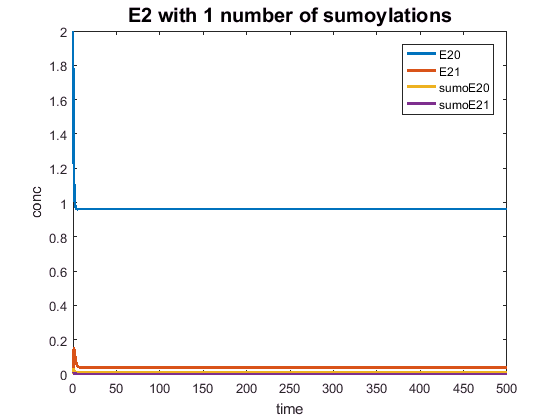

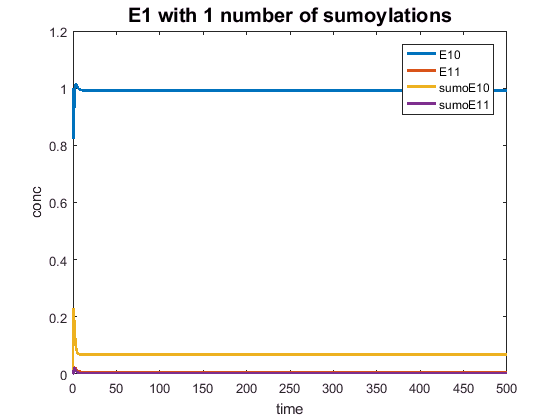

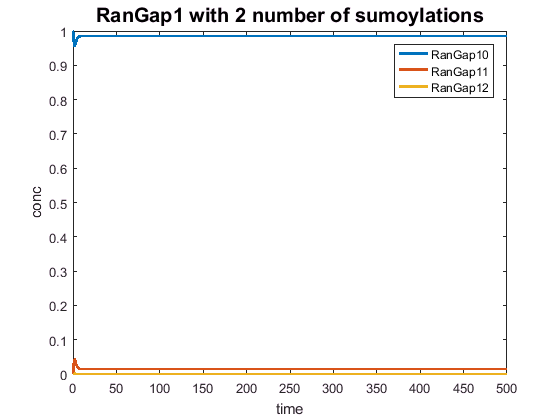

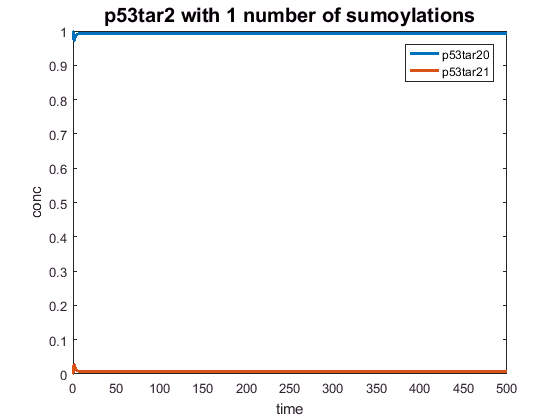

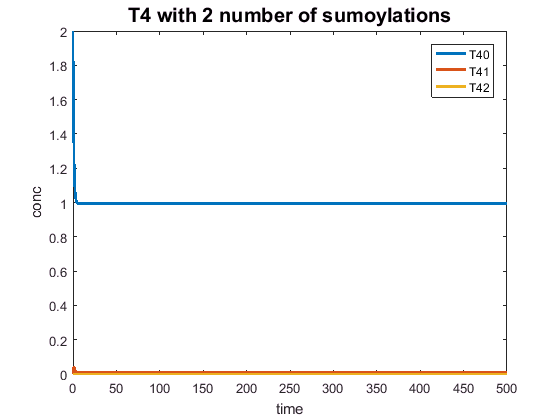

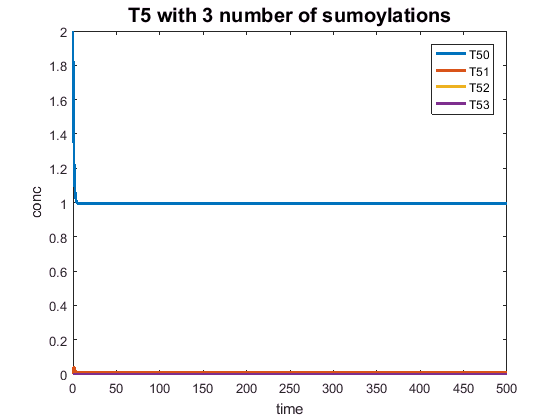

colr={'r','b','k -.','g','c','.-'};
for ctrplot = 1: size(param.numofSUMOontarget,2)
    
    if ctrplot == 2
        indtar = param.numOFconstspecies + (2*(param.numofSUMOontarget(1) + 1)) + 1;
    elseif ctrplot == 1
        indtar =  param.numOFconstspecies + 1;
    elseif ctrplot == 3  
        indtar =  param.numOFconstspecies + (2*(param.numofSUMOontarget(1) + 1)) + (2*(param.numofSUMOontarget(2) + 1)) + 1;
    else
        indtar = indtar + param.numofSUMOontarget(ctrplot - 1)+1;
    end
    
%%    indtar:indtar+param.numofSUMOontarget(ctrplot)
%%    y(end,indtar:indtar+param.numofSUMOontarget(ctrplot))
    
        if ctrplot < 3
            figure(ctrplot*100)
            plot(t,y(:,indtar:indtar+(2*param.numofSUMOontarget(ctrplot))+1),'LineWidth',2);
            
            for ctrLL=0:numofSUMOontarget(ctrplot)
                ll(ctrLL+1)=strcat(allTargets(ctrplot),num2str(ctrLL));
            end
            
            kk = strcat('sumo',ll);
            mm={ll{:} kk{:}};
            legend(mm);
              
        else

            figure(ctrplot*100)
            plot(t,y(:,indtar:indtar+param.numofSUMOontarget(ctrplot)),'LineWidth',2);
            
            for ctrLL=0:numofSUMOontarget(ctrplot)
                ll(ctrLL+1)=strcat(allTargets(ctrplot),num2str(ctrLL));
            end
            
           legend(ll);
        end
        
       
        xlabel('time');
        ylabel('conc');
        tt=sprintf('%s with %d number of sumoylations',allTargets{ctrplot},param.numofSUMOontarget(ctrplot));
        title(tt,'fontsize',15);
        
        clear ll
        
%         figure(10)
%         plot(t,y(:,indtar+param.numofSUMOontarget(ctrplot))/y0Targets(ctrplot),colr{ctrplot},'LineWidth',2);
%         hold on;
end

%% legend(allTargets);


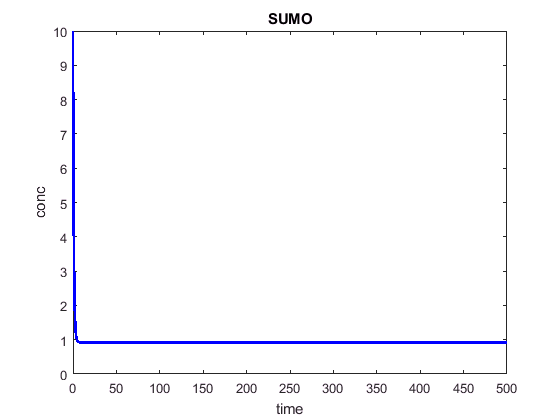

figure(1) 
plot(t,y(:,nsumo),'b','LineWidth',2); 
xlabel('time'); 
ylabel('conc'); 
title('SUMO');

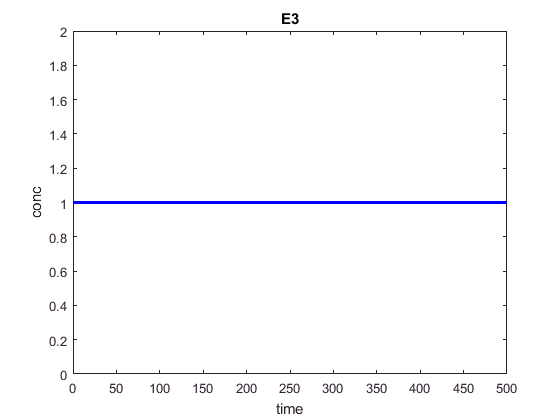

figure(2) 
plot(t,y(:,ne3),'b','LineWidth',2); 
xlabel('time');
ylabel('conc');
title('E3');

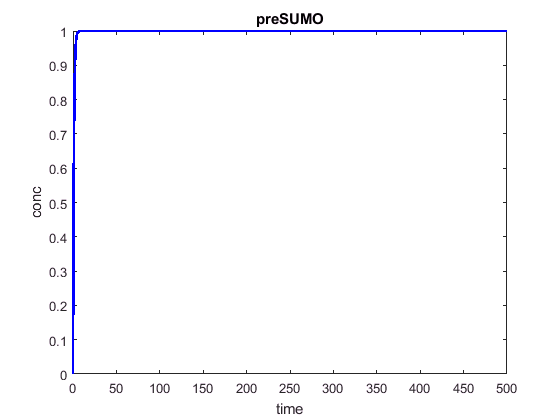

figure(3)
plot(t,y(:,npresumo),'b','LineWidth',2);
xlabel('time');
ylabel('conc');
title('preSUMO');